clear;clc;

debug = true; % 改成true就是从文件中读点坐标，要求在下面啦；false就是生成散点做测试用的

## 读入数据并画图

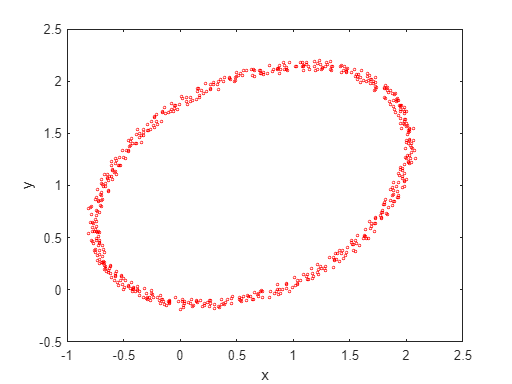

if debug % 正常模式：从文件读入散点
    x = csvread('En-3formants-5.8.xlsx'); % 读入散点，n*2矩阵
else % 否则自动生成散点
    theta = (-pi:0.01:pi)';
    a0 = 1.5; b0 = 1; cx0 = 1; cy0 = 0.5; phi00 = pi/6;
    x(:,1) = a0*cos(theta) + 0.1*rand(length(theta),1) + cx0;
    x(:,2) = b0*sin(theta) + 0.1*rand(length(theta),1) + cy0;
    R = [cos(phi00), -sin(phi00); sin(phi00), cos(phi00)];
    x = (R*x')';
end

xmin = min(x(:,1));
xmax = max(x(:,1));
ymin = min(x(:,2));
ymax = max(x(:,2));
n = size(x,1);

figure('Name', '椭圆拟合并求面积');
plot(x(:,1),x(:,2),'ro','MarkerSize',2); hold on;
xlabel('x');
ylabel('y');

## 椭圆拟合：MATLAB自己的非线性最小二乘方法

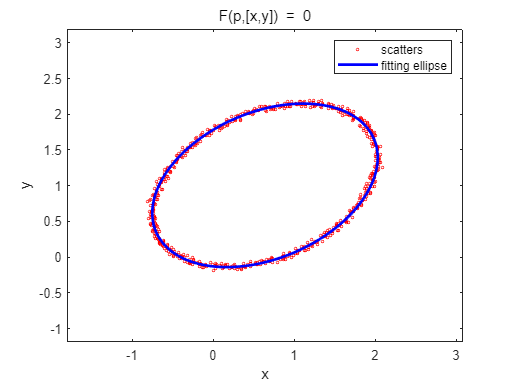

F = @(p,x) p(1)*x(:,1).^2 + p(2)*x(:,1).*x(:,2) + p(3)*x(:,2).^2 + p(4)*x(:,1) + p(5)*x(:,2) + p(6); % 椭圆一般方程
p0 = [1.5,1,1,1,1,1]; % 迭代初值
p = nlinfit(x,zeros(n,1),F,p0); % 非线性最小二乘法
% p = lsqcurvefit(F,p0,x,zeros(n,1));
h = ezplot(@(x,y)F(p,[x y]), [xmin - 1,xmax + 1,ymin - 1,ymax + 1]);
set(h,'Color','b','LineWidth',2.0);
legend('scatters','fitting ellipse');

## 求一般方程表示的椭圆面积

A = p(1);
B = p(2);
C = p(3);
D = p(4);
E = p(5);
F = p(6);
% 由一般方程求椭圆的参数
cx = (B*E - 2*C*D)/(4*A*C - B^2); % 椭圆中心x坐标
cy = (B*D - 2*A*E)/(4*A*C - B^2); % 椭圆中心y坐标
a = sqrt(2*(A*cx^2 + C*cy^2 + B*cx*cy - F)/(A + C + sqrt((A-C)^2 + B^2))); % 椭圆长轴长（x轴平行的轴长）
b = sqrt(2*(A*cx^2 + C*cy^2 + B*cx*cy - F)/(A + C - sqrt((A-C)^2 + B^2))); % 椭圆短轴长（y轴平行的轴长）
phi = 0.5*atan(B/(A - C)); % 椭圆倾角

S = pi*a*b

S = 4.7080